# Immisicble two-phase flow drainage in a subsurface reservoir - example 1 

In this tutorial two-dimensional immiscible two-phase flow drainage of oil by water injection is simulated. Permeability and porosity distributions are extracted from the first layer of the full three-dimensional geological model of [SPE10 comparative solution project](http://www.spe.org/web/csp/datasets/set02.htm). 

This tutorial involves four steps:

- First, permeabiiity and porosity data are loaded from disk files, analysed, and visualised. Next, we verify that these variables are highly correlated as expected from the data.

- Setup auxilliary simulation data, such as wells positions, their flow rates, fluid phases properties, initial pressure and saturation conditions, the time stepping parameters, and the nonlinear saturation solver options.

- Run the time simulation loop involving a sequential implicit solution procedure between pressure and saturation distributions. Next, we analyse and plot the convergence behavior and the performance of the nonlinear saturation solver.

- Post-process of the numerical results by plotting the spatial distributions of simulated pressure and saturation at the simulation end. Different presentation graphics styles such as *mapping* and *contouring* modes are explored. 

## Load and plot the petrophysical (permeability and porosity) data

We considere a simple one layer rectangular domain. In this case we explicitly set the domain lengths along each space dimension as follows

% Domain size along X, Y & Z directions
Dx = 365.76; Dy = 670.56; Dz = 0.6096;

Next, we set the number of cells along each space direction and the total number of grid cells. Next, we add those variables into the `Grid` structure

Nx = 60;
Ny = 220;
Nz = 1; 
N  = Nx*Ny*Nz;
Grid.Nx = Nx; Grid.Ny = Ny; Grid.Nz = Nz; Grid.N = N;

To fullfill the need of internal compuattional tasks we add the uniform grid spacings, `hx`, `hy`, and `hz`, along the respective directions to the `Grid` structure

Grid.hx = (Dx/Nx); Grid.hy = (Dy/Ny); Grid.hz = (Dz/Nz);

Additionally, we need to setup other few variables for the `Grid` structure such as, `V` (the uniform cells volume), and `compr` (the total compressibility). Notice that the compressibility data is a 3D shape array whose size conforms to the grid dimensions. The MATLAB command [`ones`](https://fr.mathworks.com/help/matlab/ref/ones.html)`(Nx,Ny,Nz)` constructs such an array with a unit values for all cells, and thus by multiplying it with a constant values we obtain a uniform distribution of the compressibility data over the computational domain. 

Grid.V     = (Dx/Nx)*(Dy/Ny)*(Dz/Nz);
Grid.compr = 4.4e-10.*ones(Nx,Ny,Nz);

Now, we load porosity data from a previously saved mat file '*spe_layer1_phi.mat*' which is included in the data subfolder of the included files. porosity data is stored in *phi_layer* variable (because we can store more than one array in a mat file).

load 'spe_layer1_phi.mat' phi_layer;

Now, we will check if the loaded data is within acceptable bounds. A situation which occur many often in practice. First, look if there exists porosity values below or close to 0+. This can be simply done with the following command:

length(find(phi_layer<eps))

ans = 68

indicating that the porosity is below the smallest floating point precision number [`eps`](https://fr.mathworks.com/help/matlab/ref/eps.html) (effective zero on the target computer) at 68 cells. To correct for this misleading data we set these values to a prescribed minimum porosity threshold (1e-3 herein). Otherwise, the saturation solver will fail since dividing by zero porosity will result in an overflow.

phi_layer = max (phi_layer(:), 1e-3);

The `Grid` structure is promoted with a new variable `por` conforming to the `Grid` shape. 

Grid.por = reshape(phi_layer',Nx,Ny,Nz); 

Finally, permeability data is loaded from the mat file '*spe_layer1_perm.mat*' and variable *perm_layer*. 

load 'spe_layer1_perm.mat' perm_layer;

Tha data units is converted into SI unit of the permeability (m^2) because it is given in Dary units in the SPE10 dataset. Again, the `Grid` structure is promoted with a new variable `K` conforming to the `Grid` shape but with 3 components since the permeability data assumes an anisotropic diagonal tensor. 

Grid.K = perm_layer*9.869232667160130e-13;
Grid.K = reshape(Grid.K',3,Nx,Ny,Nz); 

Now, we're ready the plot the porosity and permeability data to see how they look like. First, we will plot the porosity data in linear scale. Next, we plot permeability along X direction in log10 logarithmic scale to depict its extent over several orders of magnitude. 

To do this, a cartesian grid `G` data structure is setup from the domain extent ans spacings. This will help to do the plotting commands more efficiently.   

G = cartGrid(0:Dx/Nx:Dx, 0:Dy/Ny:Dy);

Start a new MATLAB figure and specify the colormap corrsponding the color palette to use and the number of colors in this palette.

figure;
colormap(jet(16));

Plot the porosity data into a [`subplot`](https://fr.mathworks.com/help/matlab/ref/subplot.html) in the same window but at le left hand side. The `PlotCellData` function plots a map of the variable `Grid.por` using information in the structure variable `G`. The '`EdgeColor`' option is set to '`none`' to hide the display o the gridlines of the underlying grid. Since the grid is so dense in our modl, letting this option active the resulting plot will be obsured. 

subplot(1,2,1);
PlotCellData(G, Grid.por(:), 'EdgeColor','none');

next, this plot x and y axis are set as dependent and we add a color bar and a title. 

axis tight equal; colorbar, title('Porosity map [-]');

The same sequence of commands are repeated for the right plot to obtain a map of Kx in log10 scale. 

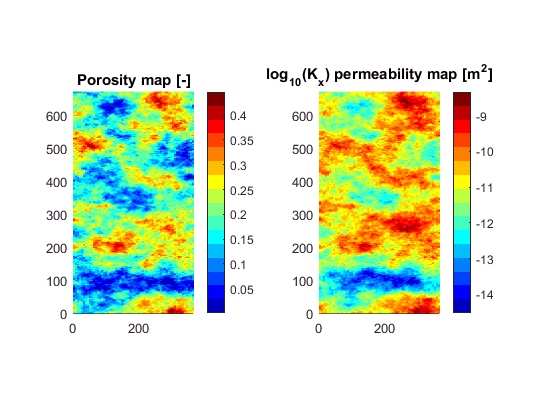

subplot(1,2,2);
PlotCellData(G, reshape(log10(Grid.K(1,:,:,:)),N,1), 'EdgeColor','none');
axis tight equal; colorbar, title('log_{10}(K_x) permeability map [m^2]');

Clear phi_layer variable from memory space since it's not needed further. This is more relevant for large scale applications or on computers with very modest ressources. 

clear phi_layer;

Now, we check if the log10-permeability and porosity fields ara correlated somehow. First, let's start with the first component of the diagonal permability tensor, Kx:

corrcoef(reshape(log10(Grid.K(1,:,:,:)),N,1),reshape(Grid.por(:,:,:),N,1))

ans =     1.0000    0.8819
    0.8819    1.0000


Off-diagonals of the correlation matrix are high positive values indicating a good positive correlation between the two variables. Let's now do the same thing for the y and z components of the permeability to conclude on their correlation with the porosity. 

corrcoef(reshape(log10(Grid.K(2,:,:,:)),N,1),reshape(Grid.por(:,:,:),N,1))

ans =     1.0000    0.8819
    0.8819    1.0000


corrcoef(reshape(log10(Grid.K(3,:,:,:)),N,1),reshape(Grid.por(:,:,:),N,1))

ans =     1.0000    0.7651
    0.7651    1.0000


## Setup auxilliary simulation data

We further add a five-spot well pattern composed from 1 injector and 4 producers. Production wells are placed at the domain corners while the injection well is located at the center. A quarter of the volumetric injection flow rate, `Qi`, is produced at each of the four production wells. 

% define some useful time units conversion constants 
second = 1; 
minute = 60*second;
hour   = 60*minute; 
day    = 24*hour; 
week   = 7*day;
month  = 30*day; 
year   = 365*day;

% Injection/production flow rates
Qi         = 25/hour;                  % total flow rate (converted from m^3/h to m^3/s)
prod_wells = [1,Nx,N-Nx+1,N];          % grid indices of production wells
Qw         = zeros(N,1);               % initialize production/injection flow rates array
Qw(prod_wells) = -Qi/4*ones(1,4);      % flow rates at production wells 
inj_well   = (Nx*(Ny-1))/2;            % grid index of injection well
Qw(inj_well)   = +Qi;                  % injection flow rate

Notice that (by convention), flow rates have to be positive for injection wells and negative for production wells. `Qw` is a distributed 1xN array which holds distributed flow rates. It has zero values everywhere except at injection/production cells. 

Next, we initialize two fluid objects `oil` and `brine` in which fluid properties data corresponding to a more dense and viscous *Oil* phase and less viscous and dense *Saltwater* phase, respectively. 

% fluid properties units: density [Kg/m^3], viscosity [Pa.s], residual saturation []
oil   = Fluid('Oil',      [1200, 3e-3,  0.3]);   % resident fluid
brine = Fluid('Saltwater',[1030, 5e-4, 1e-2]);   % injected fluid

Initialize fluid global pressure in the computational domain to a constant value of 100 bars and the initial brine saturation to its residual value (i.e. `brine.Sr`)

% define some useful pressure units conversion constants
Pascal = 1;                                      % Pascal SI unit 
bar    = 1e+5*Pascal;                            % bar
psi    = 7.042253521126761e+03*Pascal;           % UK pressure unit = lbf/in^2
atm    = 1.013249965828145e+05*Pascal;           % atmosphere eqv unit 

P = 100*bar*ones(Nx,Ny,Nz);
S = brine.Sr.*ones(N,1);

Define time stepping parameters including total simulation time, `T`, the number of time steps, `nt`, and the global time step, `dt.`

T   = 50*day;                      % 50 days
nt  = 25;                          % number of time steps
dt  = T/nt;                        % time step

For the nonlinear solvers we need to pass an optional structure with options holding the absolute tolerance, tol, and the maximum number of allowed Newton-Raphson iterations, maxiter. The latter corresponds to the inner iteration count since the most outer loop corresponds to time stepping. The last option, min_dt, is the minimum allowed time step size for the saturation solver. This is needed because, as explained later in more detail, we use an adaptive time stepping algorithm which cancels out if the time step size becomes smaller than this prescribed threshold. 

opt.tol     = 1e-5;
opt.maxiter = 100;
opt.min_dt  = 30*second;

## Run the time simulation loop - Sequential implicit solution

Now, we will build the time loop involving a sequential solution of the governing global pressure equation and the nonlinear non-wetting phase saturation equation formulated in fractional form. The pressure and saturation solvers are both implicit implying an unconditional stability regardlless of the magnitude of the selected time step. 

The pressure equation, neglecting the gravitational and capillary pressure terms is given as:


$$\phi c_t \frac{\partial P}{\partial t} = \nabla.[K \lambda_t \nabla p] + \frac{q_w}{\rho_w} +  \frac{q_o}{\rho_o}$$
 

where $c_t$ is the total compressibility, $\phi$ is the rock porosity, $P$ is the fluid pressure, $\lambda_t = \lambda_o + \lambda_w$ is the total mobility given as a sum of oil and water mobilities, respectively. A fluid phase mobility $\lambda_l$ is defined as the ratio of its relative permeability $k_{r,l}$ to its viscosity $\mu_l$. $q_w$ is the water injection/withdawal mass flow rate [M/T] and $\rho_w$ is the density of the water phase [M/L^3]. Threfore $\frac{q_w}{\rho_w}$ is the volumetric flow rate.

The saturation equation is a nonlinear diffusion-convection like equation for the water phase given as:


$$\phi \frac{\partial S_w}{\partial t} = - \nabla . (f_w \textbf{u}) + \frac{q_w}{\rho_w}$$


where $S_w$ is the water phase saturation, $f_w(S_w)$ is the saturation-dependent fractional flow function for the water phase, $\textbf{u} = \textbf{u_{w} + \textbf{u_o}$ is the total velocity (i.e. the sum of fluid velocities of each phase). 

Herein, the pressure solver is linear but requires successive updating of the total mobility of both fluid phases which is the task of `TwoPhasePressure `function. The latter wraps the *Two-Point Flux Approximation solver* (`TPFA` function) such that $\lambda_t (S_w)$ is iteratively updated from spatial distribution of water saturation calculated in the previous time step. 

The saturation solver uses an heuristic adaptive time steeping procedure combined with an inner Newton-Raphson (NR) iteration loop. During the inner NR iterations, the sparse system Jacobian matrix $\textbf{J} = [\frac{dF(S_w)}{dS_w}]$ is evaluated analytically to accelerate the algorithm convergence. If the NR iteration fails the current time step is subdivided (i.e. the number of local time steps is multiplied by 2) and the whole time step is repeated again from the beginning. The latter mechanism is called back-stepping. The local NR failure is due to either (i) an insuffisant or small number of allowed maximal iterations to achieve the required accuracy. Hence, when setting the NR options the user should keep a good balance between the `maxiter` and `tol` options; (ii) second, to a high or very difficult level of prescribed accuracy which cannot be achived for badly preconditioned problems. So, the absolute tolerance should be kept to reasonable values (in practice values between 1e-3 and 1e-4 are suggested); (iii) and finally, when the selected global time step results in large local pressure jumps, the same time step is generally inappropriate for the saturation solver implying a smaller time step advancement of the saturation solver to absorp the sudden numerical shock caused by the large pressure jump. 

In general, this adaptive time stepping strategy is effective in practice. Very often the algorithm starts with smaller saturation time steps at the begining of the simulation when initial conditions are far from the expected solution. This sub-time step will gradually increase in the next time levels if there is no abrupt changes in the boundary conditions (i.e. wells pumping or production schedules) or materials and fluids properties. 

Let's run this two-phase flow oil drainage simulation

tic;              % start timing the time marching loop
for t=1:nt
   fprintf('\n'); 
   fprintf('Solving two-phase flow problem. Time = %f days\n', t*dt/day);
   
   % call TPFA flow solver adapted to two-phase flow 
   [P,V] = TwoPhasePressure(Grid,S,brine,oil,Qw,P,dt); 
   
   % solve for brine saturation 
   [S,out(t)] = ImplicitSaturation(Grid,S,brine,oil,V,Qw,dt,opt);
   
   % quit any time step if the saturation solver fails 
   if out(t).convergence==false, break; end
end

Solving two-phase flow problem. Time = 2.000000 days


...........
Converged in 11 time backsteps and 4285 Newton-Raphson iterations


Solving two-phase flow problem. Time = 4.000000 days


....
Converged in 4 time backsteps and 82 Newton-Raphson iterations


Solving two-phase flow problem. Time = 6.000000 days


....
Converged in 4 time backsteps and 94 Newton-Raphson iterations


Solving two-phase flow problem. Time = 8.000000 days


....
Converged in 4 time backsteps and 97 Newton-Raphson iterations


Solving two-phase flow problem. Time = 10.000000 days


..
Converged in 2 time backsteps and 35 Newton-Raphson iterations


Solving two-phase flow problem. Time = 12.000000 days


..
Converged in 2 time backsteps and 29 Newton-Raphson iterations


Solving two-phase flow problem. Time = 14.000000 days


..
Converged in 2 time backsteps and 29 Newton-Raphson iterations


Solving two-phase flow problem. Time = 16.000000 days


.
Converged in 1 time backsteps and 14 Newton-Raphson iterations


Solving two-phase flow problem. Time = 18.000000 days


.
Converged in 1 time backsteps and 14 Newton-Raphson iterations


Solving two-phase flow problem. Time = 20.000000 days


.
Converged in 1 time backsteps and 15 Newton-Raphson iterations


Solving two-phase flow problem. Time = 22.000000 days


Converged in 0 time backsteps and 9 Newton-Raphson iterations


Solving two-phase flow problem. Time = 24.000000 days


Converged in 0 time backsteps and 7 Newton-Raphson iterations


Solving two-phase flow problem. Time = 26.000000 days


Converged in 0 time backsteps and 5 Newton-Raphson iterations


Solving two-phase flow problem. Time = 28.000000 days


Converged in 0 time backsteps and 7 Newton-Raphson iterations


Solving two-phase flow problem. Time = 30.000000 days


Converged in 0 time backsteps and 5 Newton-Raphson iterations


Solving two-phase flow problem. Time = 32.000000 days


Converged in 0 time backsteps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 34.000000 days


Converged in 0 time backsteps and 10 Newton-Raphson iterations


Solving two-phase flow problem. Time = 36.000000 days


Converged in 0 time backsteps and 7 Newton-Raphson iterations


Solving two-phase flow problem. Time = 38.000000 days


Converged in 0 time backsteps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 40.000000 days


Converged in 0 time backsteps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 42.000000 days


Converged in 0 time backsteps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 44.000000 days


Converged in 0 time backsteps and 7 Newton-Raphson iterations


Solving two-phase flow problem. Time = 46.000000 days


Converged in 0 time backsteps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 48.000000 days


Converged in 0 time backsteps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 50.000000 days


Converged in 0 time backsteps and 5 Newton-Raphson iterations


toc;

Elapsed time is 23.195861 seconds.


From the convergence output we notice that this sequential solution algorithm went very smoothly. There was a difficulty to reach convergence in the first time step because it seems that 2 days time step was very large for the saturation solver. Hence, the initial time step was automatically subdivided 11 times resulting to an effective saturation time step close to 84 seconds as shown below from the fields of the returned output structure `out` for the first time period. The `dt` field returns the selected time step by the saturation solver during this period. 

out(1)

ans =       convergence: 1
        backsteps: 11
               dt: 84.375000000000000
    nr_iterations: 4285


Now, we plot a summary of the saturation solver performance during the simulation. In the left side of the figure we plot the evolution of the internally selected time step versus time, while in the right figure the evolution of the total number of inner Newton-Raphson iterations versus time is plotted. Both figure are best depicted using a [`semilogy`](https://fr.mathworks.com/help/matlab/ref/semilogy.html) axis. 

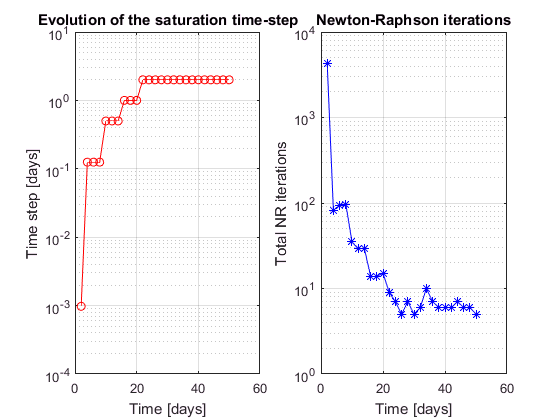

figure; 

subplot(1,2,1); 
for t=1:nt, dt_history(t) = out(t).dt; end 
semilogy((1:nt)*dt/day, dt_history/day, '-ro'); 
title('Evolution of the saturation time-step'); xlabel('Time [days]'); ylabel('Time step [days]'); grid on;

subplot(1,2,2); 
for t=1:nt, nr_history(t) = out(t).nr_iterations; end 
semilogy((1:nt)*dt/day, nr_history, '-b*'); 
title('Newton-Raphson iterations'); xlabel('Time [days]'); ylabel('Total NR iterations'); grid on;

We observe thet the internal saturation time step gradually increases to 1.5 hour, 6 hours, 12 hours and finally to 2 days starting from 22 days after the simulation start. So, afterwards the pressure and saturation time steps becomes equal meaning that the saturation extent of the plume becomes significant enough to amortize the pressure jumps immediately. 

**Post-processing of the numerical solution - mapping mode**

Since the main simulated variables are pressure $P$ and water saturation $S_w$ we will plot them directly using the supplied functions which make use of MATLAB's excellent built-in graphics capabilities without writing the results into intermediate text or binary files in a required format and loading them back from an external third-party post-processing software. So, with very few commands we get directly the results ready for quality publication freeing the modeller from all intermediate tasks and hence speeding the data-processing-simulation-post-processing workflow significantly. 

We will use here the routine `PlotCellData` to produce the figures in *mapping* mode where each cell in the grid is plotted with a constant color corresponding to a linearly interpolated value between the upper and lower colors in the used color palette. This palette fits the range between the maximal and minimal values detected in the data array.  

The [`figure`](https://fr.mathworks.com/help/matlab/ref/figure.html) command without any argument opens a new MATLAB figure (or axis in MATLAB's terminology) so that the previously opened figures are preserved and all following drawing commands will be placed in this new figure. The [`colormap`](https://fr.mathworks.com/help/matlab/ref/colormap.html) command is optionally called before the drawing commands to choose among the available color palettes, here we choose the [`jet`](https://fr.mathworks.com/help/matlab/ref/jet.html) palette with 256 colors distributed between blue and red. 

figure; 
colormap(jet(256));

Next, we plot the pressure after conversion from `Pascal` to `bar` units. We call the [`subplot`](https://fr.mathworks.com/help/matlab/ref/subplot.html) command to specify that we want to make a plot matrix with 1 row and 2 columns in the target figure. The last argument in the subplot command is the active subplot to which the next plotting commands are directed. The `PlotCellData` function takes additional property-value pairs (à la MATLAB). These options are exactly those supported by the low level [`patch`](https://fr.mathworks.com/help/matlab/ref/patch.html) command to control the internal details of the plot. To study all these options type `help patch` command or go to [`patch`](https://fr.mathworks.com/help/matlab/ref/patch.html) window in the online help system.  Here the '`EdgeColor`' property specifies the color of the underlying grid edges, by setting this property to '`none`' they will be hidden in the current plot. In this example the grid is very dense. So, drawing all grid edges will obscure the reulting plots but in other applications where the grid is coarse this might not be necessary.

% plot fluid pressure on left side of current figure
subplot(1,2,1);
PlotCellData(G, P(:)/bar, 'EdgeColor','none');

By default MATLAB plots fit to the rectangular window inside which they're displayed. A good idea here is to call the [`axis`](https://fr.mathworks.com/help/matlab/ref/axis.html) command to make x and y axis scales dependent using `equal `option. Likewise, `tight` wil readjust the plot to fit at best to actual window after axis scaling. Finally, we decorate the plot with a [`colorbar`](https://fr.mathworks.com/help/matlab/ref/colorbar.html) and a custom [`title`](https://fr.mathworks.com/help/matlab/ref/title.html). 

axis tight equal; colorbar; title('Pressure [bar]');

We follow the same previous steps to plot the water saturation in our computational domain. 

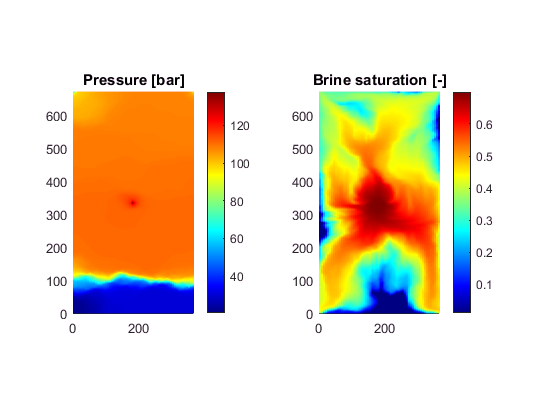

% plot brine saturation on the right side of current figure
subplot(1,2,2);
PlotCellData(G, S(:), 'EdgeColor','none');
axis tight equal; colorbar, title('Brine saturation [-]');

**Post-processing of the numerical solution - contouring mode**

Presenting the results in mapping mode is most natural when working with cell-centered discretization methods. It has also the advantage to appreciate the dispersion of the saturation plume as seen in the right plot of the above figure. But, it has other limitations. For instance, the gradient of the plotted variable cannot be easily appreciated in some areas, the presentations graphics quality may deteriorate when saving the figure into raster file formats, and this presentation mode is not suitable for explanation to non-specialists such as managers and decision makers. 

Another presentation mode which is quite popular in all fields of geosciences in *contouring*. The target variable iso-values are traced by a general purpose algorithm to contour the data. Such presentation mode is mainly supported by basic MATLAB routines such as [`contour`](https://fr.mathworks.com/help/matlab/ref/contour.html), [`contourc`](https://fr.mathworks.com/help/matlab/ref/contourc.html), [`contourf`](https://fr.mathworks.com/help/matlab/ref/contourf.html) and [`contour3`](https://fr.mathworks.com/help/matlab/ref/contour3.html). We will use `PlotContourData` function which is a simple wrapper to `contourf` or `contour` to plot filled or simple contour plots, respectively. This function arguments are similar to those of `PlotCellData` function except for the optional arguments are property-value pairs which are compatible with those of the `contourf` or `contour` commands. 

So, make a figure made from two contour plots of water pressure and saturation. We plot pressure contour lines between 20 and 140 bars with an interval of 20 bars. We select saturation contour lines between 0 and 0.7 with 5% interval. 

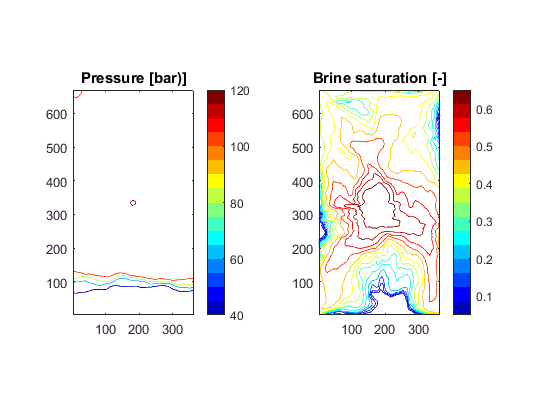

figure;
opts.fill = 'off';   % change this option to 'on' for contour filled plots
% plot water pressure on left side 
subplot(1,2,1);
PlotContourData(G, P(:)/bar,opts,'LevelList',20:20:140);
colormap(jet(16));
axis tight equal; colorbar, title('Pressure [bar)]');
% plot water saturation on right side 
subplot(1,2,2);
PlotContourData(G, S(:),opts,'LevelList',0:0.05:0.7);
axis tight equal; colorbar, title('Brine saturation [-]');

To better understand the spatial distribution of brine saturation we also plot its probability distribution reflecting the saturation volumetrics inside the reservoir. To do that we call the [`histogram`](https://fr.mathworks.com/help/matlab/ref/histogram.html) command for $S$ variable with 7 bins as a second argument and '`probability`' value for the '`Normalization`' option. This means that the height of each bar is the relative number of cell-centered saturation items (number of saturation values in bin / total number of grid cells). The sum of the bar heights is obviously equal to 1.

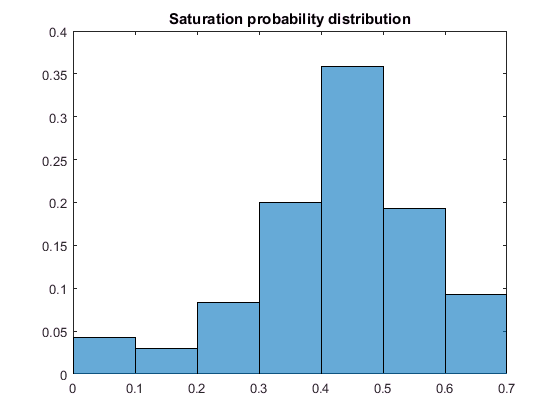

figure;
histogram(S,7,'Normalization','probability');
title('Saturation probability distribution');

Around 35% of the reservoir volume is filled with water saturations between 0.4 and 0.5 while around 75% of the reservoir volume is filled with water saturations between 0.3 and 0.6 which are clearly the dominant modes of saturations after 50 days of oil drainage by water injection. 

## Conclusions

In merely a little bit more than 100 lines of MATLAB commands (including blank and comment lines) we were able in this tutorial to build a script performing the following tasks: 

- Read petrophysical data from disk files, plot, and analyse them.

- Setup auxilliary simulation data.

- Run an immiscible two-phase flow drainage simultion involving an implicit sequential simulation procedure, analyse and plot the convergence behavior of the adaptive time stepping algorithm. 

- Post-process the numerical solution using mapping and contouring modes, then analyse the spatial distribution of water saturation after 50 days of oil drainage. 

All these steps take less than 1 minute CPU time in a commodity PC. With a scripting technology the time traditionally taken in file and data transfer between pre-processing, simulation, and post-processing tools as in existing workflows is cutted to its minimum. Hence, the modeller can spend more time to gain in problem understanding rather than loosing a significant project timeframe in useless data manipulation tasks.